# **Assignment:  Feature Extraction of CWRU Dataset**

**Name: Joungbin Choi  **

**Student ID: 22200757**

**Data: 2025/11/10**

## **Instruction**

1. **Read the paper and understand the whole process**

This Assignment is implementation a part of Feature Extration in  the literature 

[Download here](https://github.com/ykkimhgu/HGU_IAIA/tree/main/Docs)

- Rauber, T. W., de Assis Boldt, F., & Varejao, F. M. (2015, January). Heterogeneous Feature Models and Feature Selection Applied to Bearing Fault Diagnosis. *IEEE Transactions on Industrial Electronics*. Institute of Electrical and Electronics Engineers (IEEE).

**2. Extract and Analyze  Features**

**3. Compare  Features among different classes**

**Other reference**

Diagnostics 101: A Tutorial for Fault Diagnostics of Rolling Element Bearing Using Envelope Analysis in MATLAB 

[Matlab code]: [https://www.kau-sdol.com/matlab-code](https://www.kau-sdol.com/matlab-code)

## Dataset

**A sample of selected  CWRU bearing dataset **

- 1 data file for each fault state under specific condition

Download a selected sample of  CWRU Dataset ([**download here**](https://github.com/ykkimhgu/HGU_IAIA/tree/main/Dataset/CWRU_selected_dataset))

- Download   **Raw_data.zip**  

- `/Dataset/CWRU_selected_dataset/Raw_data/`

It should be located in your local folder of

- `/Dataset/CWRU_selected_dataset/Raw_data/`

Sampling: 

- **Drive end bearing(12K): 12,000 samples/second**

Classes:

- Normal / Outer Race fault / Inner Race fault 

- Each under 1HP load,  fault diameter of 0.007inches

Variables

- DE - drive end accelerometer data

- FE - fan end accelerometer data

- BA - base accelerometer data

- time - time series data

- RPM - shaft rpm during testing

### Drive End Bearing Experiment- 12K

## 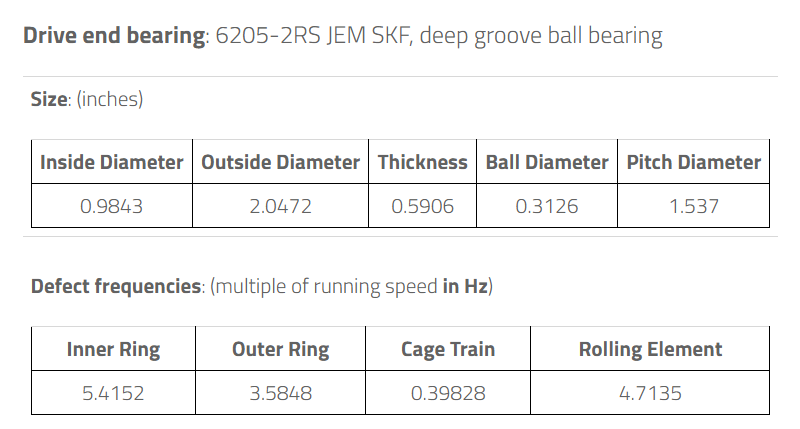

## Load Dataset

close all
clear
addpath('../IAIA/Library')

% load("../IAIA/Dataset/CWRU_selected_dataset/Raw_data/ball_007_1hp.mat");
data_ball = load('../IAIA/Dataset/CWRU_selected_dataset/Raw_data/ball_007_1hp.mat');
ball_DE     = data_ball.X119_DE_time;
ball_FE     = data_ball.X119_FE_time;
ball_BA     = data_ball.X119_BA_time;
ball_RPM    = data_ball.X119RPM;

data_inner = load('../IAIA/Dataset/CWRU_selected_dataset/Raw_data/inner_007_1hp.mat');
inner_DE     = data_inner.X106_DE_time;
inner_FE     = data_inner.X106_FE_time;
inner_BA     = data_inner.X106_BA_time;
inner_RPM    = data_inner.X106RPM;

data_normal = load('../IAIA/Dataset/CWRU_selected_dataset/Raw_data/normal_1hp.mat');
normal_DE     = data_normal.X098_DE_time;
normal_FE     = data_normal.X098_FE_time;

data_outer = load('../IAIA/Dataset/CWRU_selected_dataset/Raw_data/outer_007_1hp.mat');
outer_DE     = data_outer.X131_DE_time;
outer_FE     = data_outer.X131_FE_time;
outer_BA     = data_outer.X131_BA_time;
outer_RPM    = data_outer.X131RPM;

fs = 12000;     % [Hz]
ts = 1.0 / fs;  % [sec]

defect_f_inner = inner_RPM / 60.0;
defect_f_outer = outer_RPM / 60.0;

ball_d  = 0.3126;
pitch_d = 1.537;

BPFO = 3.5848 * 30;
BPFI = 5.4152 * 30;

## **Preprocessing**

**raw data plotting**

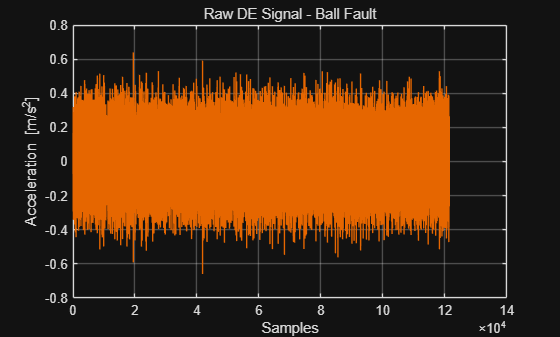

figure;
plot(ball_DE, 'Color',[0.9 0.4 0])
title('Raw DE Signal - Ball Fault')
xlabel('Samples'); ylabel('Acceleration [m/s^2]'); grid on;

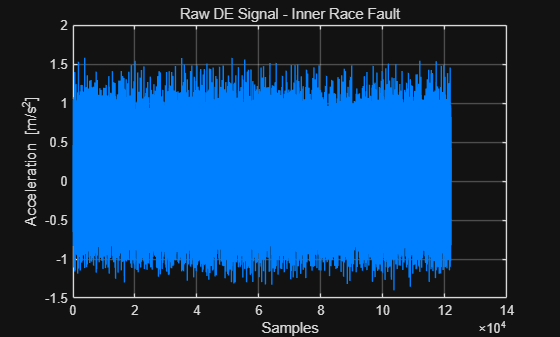


figure;
plot(inner_DE, 'Color',[0 0.5 1])
title('Raw DE Signal - Inner Race Fault')
xlabel('Samples'); ylabel('Acceleration [m/s^2]'); grid on;

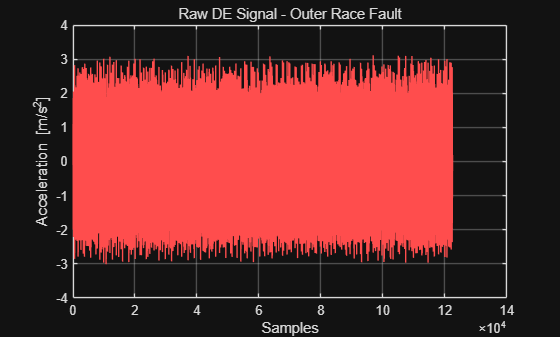


figure;
plot(outer_DE, 'Color',[1 0.3 0.3])
title('Raw DE Signal - Outer Race Fault')
xlabel('Samples'); ylabel('Acceleration [m/s^2]'); grid on;

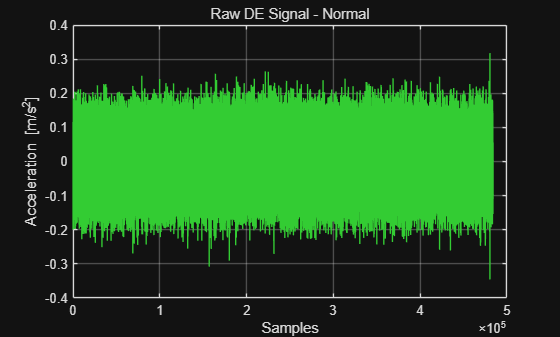


figure;
plot(normal_DE, 'Color',[0.2 0.8 0.2])
title('Raw DE Signal - Normal')
xlabel('Samples'); ylabel('Acceleration [m/s^2]'); grid on;

BallFeat_DE     = extractFeatures_CWRU(ball_DE, fs);
BallFeat_FE     = extractFeatures_CWRU(ball_FE, fs);

InnerFeat_DE    = extractFeatures_CWRU(inner_DE, fs);
InnerFeat_FE    = extractFeatures_CWRU(inner_FE, fs);

OuterFeat_DE    = extractFeatures_CWRU(outer_DE, fs);
OuterFeat_FE    = extractFeatures_CWRU(outer_FE, fs);

NormalFeat_DE   = extractFeatures_CWRU(normal_DE, fs);
NormalFeat_FE   = extractFeatures_CWRU(normal_FE, fs);

## **Features Extraction Function**

• Extract Time-Domain Features

- Mean, Std, Skewness, Kurtosis, Peak2Peak, RMS, CrestFactor,  ShapeFactor, ImpulseFactor, MarginFactor, Energy etc

• Extract Frequency-Domain Features

-   Basic features,  SKMean, SKStd, SKSkewness, SKKurtosis, etc

• Envelop Extraction

• Plot  STFT 

• Plot  Kurtogram

• Analyze Spectral Kurtosis

function Features = extractFeatures_CWRU(x, fs)

x = x(:);
L = length(x);

Features = struct;

% Time-domain features
Features.Time = timeFeatures_student(x);


% FFT
FFT_raw = getFFT_student(x, L);

     Class        mean         std         rms         sra         aav       energy     peak       ppv        if        sf        cf        mf         sk          kt  
    ________    _________    ________    ________    ________    ________    ______    _______    ______    ______    ______    ______    ______    _________    ______

    "Ball"      0.0038918     0.13901     0.13907    0.094363     0.11122    2348.1    0.65965    1.2993    5.9312    1.2504    4.7433    6.9905    0.0074533    2.9638
    "Inner"      0.005801     0.29284     0.29289     0.16484     0.20764     10465     1.5808    2.9838    7.6131    1.4105    5.3973    9.5902      0.13043    5.5423
    "Outer"     0.0040611     0.59194     0.59195     0.26626     0.36646     42898     3.1123    6.1242    8.4927    1.6153    5.2577    11.689     0.033401     7.595
    "Normal"     0.012564    0.065152    0.066352    0.045547    0.053471    2130.4    0.34588    0.6634    6.4686    1.2409    5.2129     7.594     -0.17305  

Features.FFT.Raw = FFT_raw;

% Frequency-domain statistical features
Features.Freq = freqFeatures_student(FFT_raw);


% 3) Envelope
% env = envelopExtract(x);
% Features.Envelope = env;

[pEnv, fEnv, xEnv, tEnv] = envspectrum(x,fs);
Features.EnvelopeSpectrum.Value     = pEnv;
Features.EnvelopeSpectrum.Frequency = fEnv;

     Class        mean        std         rms         sra         aav       energy     peak        ppv        if        sf        cf        mf          sk          kt  
    ________    ________    ________    ________    ________    ________    ______    _______    _______    ______    ______    ______    ______    __________    ______

    "Ball"      0.032982    0.081696    0.088102    0.059998    0.070653    942.37    0.38461    0.69608    5.4437     1.247    4.3655    6.4104    -0.0086332    2.9018
    "Inner"     0.033327     0.23771     0.24003     0.16039     0.18989    7028.5     1.1526     2.1195    6.0698     1.264    4.8019    7.1861      -0.14794    3.3562
    "Outer"     0.032774     0.25634     0.25842     0.16415     0.19862      8176     1.0667     2.1028    5.3707    1.3011    4.1278    6.4984       0.06755    3.4468
    "Normal"    0.032375    0.067346    0.074724    0.050323    0.059494    2701.9    0.32195    0.54014    5.4114     1.256    4.3085    6.3976       0.1

Features.EnvelopeSpectrum.Signal    = xEnv;
Features.EnvelopeSpectrum.Time      = tEnv;

% Envelope FFT
% env_fft = getFFT_student(env, length(env));
% Features.EnvelopeFFT = env_fft;


% STFT
[S, F_stft, T_stft] = stft(x, fs);
Features.STFT.S = S;
Features.STFT.F = F_stft;
Features.STFT.T = T_stft;

     Class          fc           rmsf          rvf    
    ________    __________    __________    __________

    "Ball"      0.00026417    0.00079807    0.00075308
    "Inner"     0.00051132      0.001677     0.0015971
    "Outer"     0.00083659     0.0033835     0.0032785
    "Normal"    4.1395e-05    0.00018905    0.00018446




% % Spectral Kurtosis
% [SK, fsk] = pkurtosis(x, fs);
% Features.SK.Value = SK;
% Features.SK.Freq  = fsk;
% 
% % Kurtogram
% Features.Kurtogram = kurtogram(x, fs);
end

## **Features Visualization**

### 1. Time/Frequency Domain Features

BallFeat_DE.Time.Class = "Ball";
BallFeat_DE.Time = movevars(BallFeat_DE.Time, 'Class', 'Before', 1);
InnerFeat_DE.Time.Class = "Inner";
InnerFeat_DE.Time = movevars(InnerFeat_DE.Time, 'Class', 'Before', 1);

     Class          fc           rmsf          rvf    
    ________    __________    __________    __________

    "Ball"      0.00017076    0.00048765    0.00045677
    "Inner"     0.00040323     0.0013678      0.001307
    "Outer"     0.00046949     0.0014712     0.0013943
    "Normal"    4.0102e-05    0.00020451    0.00020054



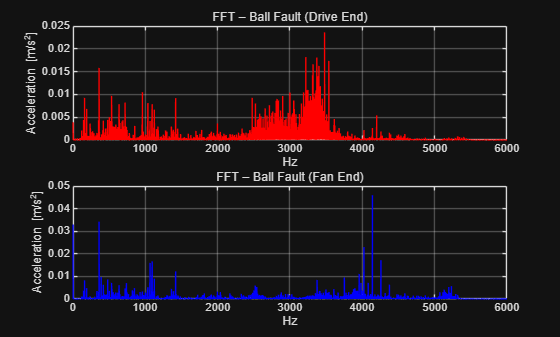

OuterFeat_DE.Time.Class = "Outer";
OuterFeat_DE.Time = movevars(OuterFeat_DE.Time, 'Class', 'Before', 1);
NormalFeat_DE.Time.Class = "Normal";
NormalFeat_DE.Time = movevars(NormalFeat_DE.Time, 'Class', 'Before', 1);

All_time_features_DE = [BallFeat_DE.Time; InnerFeat_DE.Time; OuterFeat_DE.Time; NormalFeat_DE.Time];

% Drive End Time Features
disp(All_time_features_DE);
BallFeat_FE.Time.Class = "Ball";
BallFeat_FE.Time = movevars(BallFeat_FE.Time, 'Class', 'Before', 1);
InnerFeat_FE.Time.Class = "Inner";
InnerFeat_FE.Time = movevars(InnerFeat_FE.Time, 'Class', 'Before', 1);
OuterFeat_FE.Time.Class = "Outer";
OuterFeat_FE.Time = movevars(OuterFeat_FE.Time, 'Class', 'Before', 1);
NormalFeat_FE.Time.Class = "Normal";
NormalFeat_FE.Time = movevars(NormalFeat_FE.Time, 'Class', 'Before', 1);

All_time_features_FE = [BallFeat_FE.Time; InnerFeat_FE.Time; OuterFeat_FE.Time; NormalFeat_FE.Time];

% Fan End Time Features
disp(All_time_features_FE);
BallFeat_DE.Freq.Class = "Ball";
BallFeat_DE.Freq = movevars(BallFeat_DE.Freq, 'Class', 'Before', 1);
InnerFeat_DE.Freq.Class = "Inner";
InnerFeat_DE.Freq = movevars(InnerFeat_DE.Freq, 'Class', 'Before', 1);
OuterFeat_DE.Freq.Class = "Outer";
OuterFeat_DE.Freq = movevars(OuterFeat_DE.Freq, 'Class', 'Before', 1);
NormalFeat_DE.Freq.Class = "Normal";
NormalFeat_DE.Freq = movevars(NormalFeat_DE.Freq, 'Class', 'Before', 1);

All_freq_features_DE = [BallFeat_DE.Freq; InnerFeat_DE.Freq; OuterFeat_DE.Freq; NormalFeat_DE.Freq];


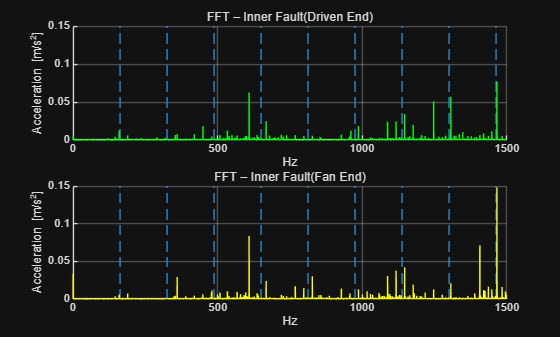

% Drive End Frequency Features
disp(All_freq_features_DE);
BallFeat_FE.Freq.Class = "Ball";
BallFeat_FE.Freq = movevars(BallFeat_FE.Freq, 'Class', 'Before', 1);
InnerFeat_FE.Freq.Class = "Inner";
InnerFeat_FE.Freq = movevars(InnerFeat_FE.Freq, 'Class', 'Before', 1);
OuterFeat_FE.Freq.Class = "Outer";
OuterFeat_FE.Freq = movevars(OuterFeat_FE.Freq, 'Class', 'Before', 1);
NormalFeat_FE.Freq.Class = "Normal";
NormalFeat_FE.Freq = movevars(NormalFeat_FE.Freq, 'Class', 'Before', 1);

All_freq_features_FE = [BallFeat_FE.Freq; InnerFeat_FE.Freq; OuterFeat_FE.Freq; NormalFeat_FE.Freq];

% Fan End Frequency Features
disp(All_freq_features_FE);

### 2. Fast Fourier Transform Features

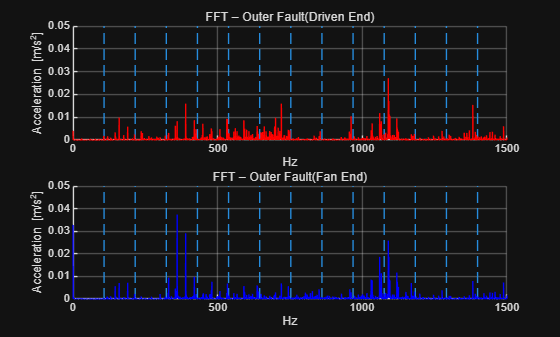

FFT_ball_DE   = BallFeat_DE.FFT.Raw;
FFT_inner_DE  = InnerFeat_DE.FFT.Raw;
FFT_outer_DE  = OuterFeat_DE.FFT.Raw;
FFT_normal_DE = NormalFeat_DE.FFT.Raw;

FFT_ball_FE   = BallFeat_FE.FFT.Raw;
FFT_inner_FE  = InnerFeat_FE.FFT.Raw;
FFT_outer_FE  = OuterFeat_FE.FFT.Raw;
FFT_normal_FE = NormalFeat_FE.FFT.Raw;

f_ball_DE = fs * (0:length(FFT_ball_DE)-1) / (2*(length(FFT_ball_DE)-1));
f_ball_FE = fs * (0:length(FFT_ball_FE)-1) / (2*(length(FFT_ball_FE)-1));
f_inner_DE = fs * (0:length(FFT_inner_DE)-1) / (2*(length(FFT_inner_DE)-1));
f_inner_FE = fs * (0:length(FFT_inner_FE)-1) / (2*(length(FFT_inner_FE)-1));


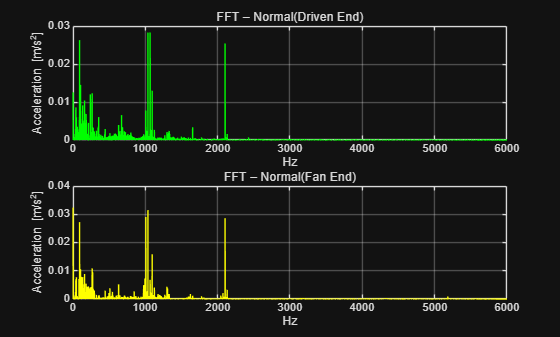

f_outer_DE = fs * (0:length(FFT_outer_DE)-1) / (2*(length(FFT_outer_DE)-1));
f_outer_FE = fs * (0:length(FFT_outer_FE)-1) / (2*(length(FFT_outer_FE)-1));
f_normal_DE = fs * (0:length(FFT_normal_DE)-1) / (2*(length(FFT_normal_DE)-1));
f_normal_FE = fs * (0:length(FFT_normal_FE)-1) / (2*(length(FFT_normal_FE)-1));


figure;
subplot(2,1,1)
plot(f_ball_DE, FFT_ball_DE, 'r'); grid on;

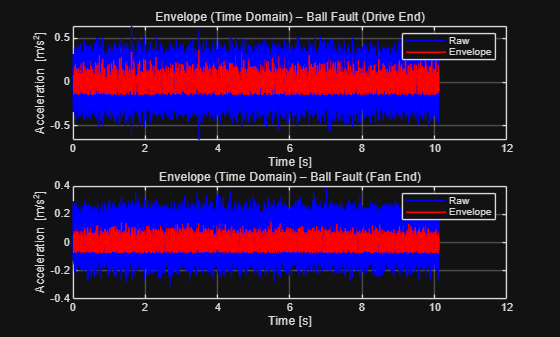

title("FFT – Ball Fault (Drive End)");
xlabel("Hz"); ylabel("Acceleration [m/s^2]");

subplot(2,1,2)
plot(f_ball_FE, FFT_ball_FE, 'b'); grid on;
title("FFT – Ball Fault (Fan End)");
xlabel("Hz"); ylabel("Acceleration [m/s^2]");
figure;
subplot(2,1,1)
helperPlotCombs(30, BPFI); hold on;
plot(f_inner_DE, FFT_inner_DE, 'g'); grid on;
title("FFT – Inner Fault(Driven End)");
xlabel("Hz"); ylabel("Acceleration [m/s^2]");
ylim([0, 0.15])
xlim([0, 1500])
subplot(2,1,2)
helperPlotCombs(30, BPFI); hold on;

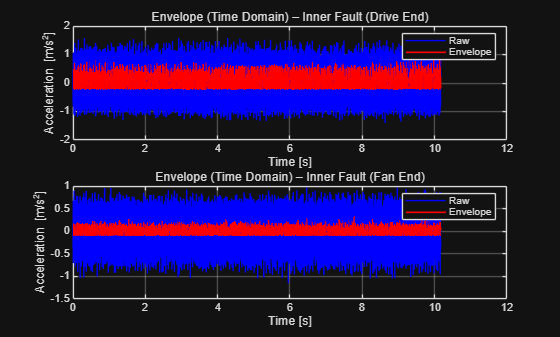

plot(f_inner_FE, FFT_inner_FE, 'y'); grid on;
title("FFT – Inner Fault(Fan End)");
xlabel("Hz"); ylabel("Acceleration [m/s^2]");
ylim([0, 0.15])
xlim([0, 1500])
figure;
subplot(2,1,1)
helperPlotCombs(40, BPFO); hold on;
plot(f_outer_DE, FFT_outer_DE, 'r'); grid on;
title("FFT – Outer Fault(Driven End)");
xlabel("Hz"); ylabel("Acceleration [m/s^2]");
ylim([0, 0.05])
xlim([0, 1500])
subplot(2,1,2)

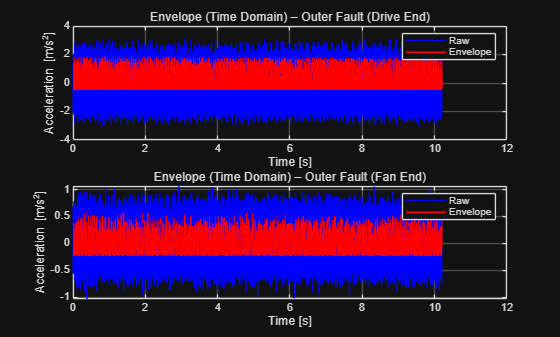

helperPlotCombs(40, BPFO); hold on;
plot(f_outer_FE, FFT_outer_FE, 'b'); grid on;
title("FFT – Outer Fault(Fan End)");
xlabel("Hz"); ylabel("Acceleration [m/s^2]");
ylim([0, 0.05])
xlim([0, 1500])
figure;
subplot(2,1,1)
plot(f_normal_DE, FFT_normal_DE, 'g'); grid on;
title("FFT – Normal(Driven End)");
xlabel("Hz"); ylabel("Acceleration [m/s^2]");
subplot(2,1,2)
plot(f_normal_FE, FFT_normal_FE, 'y'); grid on;
title("FFT – Normal(Fan End)");

xlabel("Hz"); ylabel("Acceleration [m/s^2]");

### 3. Envelop Extraction Data

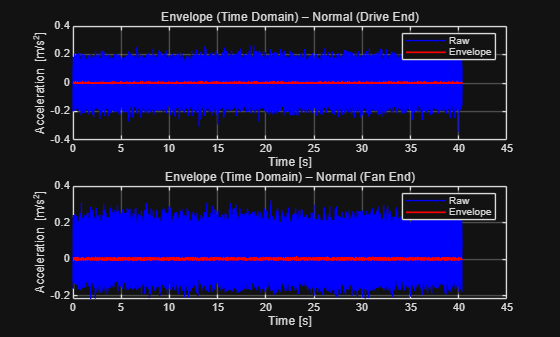

figure;
subplot(2,1,1);
plot(BallFeat_DE.EnvelopeSpectrum.Time, ball_DE, 'b'); hold on;
plot(BallFeat_DE.EnvelopeSpectrum.Time, BallFeat_DE.EnvelopeSpectrum.Signal, 'r', 'LineWidth', 1.2);
title("Envelope (Time Domain) – Ball Fault (Drive End)");
xlabel("Time [s]"); ylabel("Acceleration [m/s^2]");
legend("Raw","Envelope"); grid on;

subplot(2,1,2);
plot(BallFeat_FE.EnvelopeSpectrum.Time, ball_FE, 'b'); hold on;
plot(BallFeat_FE.EnvelopeSpectrum.Time, BallFeat_FE.EnvelopeSpectrum.Signal, 'r', 'LineWidth', 1.2);
title("Envelope (Time Domain) – Ball Fault (Fan End)");
xlabel("Time [s]"); ylabel("Acceleration [m/s^2]");

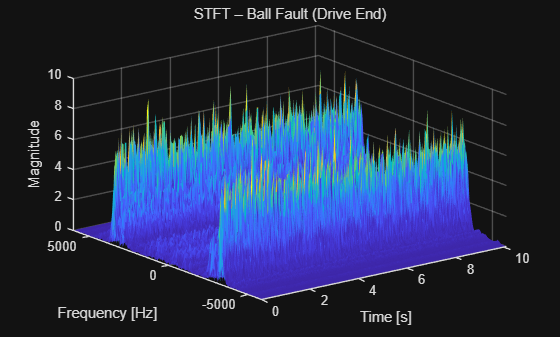

legend("Raw","Envelope"); grid on;
figure;
subplot(2,1,1);
plot(InnerFeat_DE.EnvelopeSpectrum.Time, inner_DE, 'b'); hold on;
plot(InnerFeat_DE.EnvelopeSpectrum.Time, InnerFeat_DE.EnvelopeSpectrum.Signal, 'r', 'LineWidth', 1.2);
title("Envelope (Time Domain) – Inner Fault (Drive End)");
xlabel("Time [s]"); ylabel("Acceleration [m/s^2]");
legend("Raw","Envelope"); grid on;

subplot(2,1,2);
plot(InnerFeat_FE.EnvelopeSpectrum.Time, inner_FE, 'b'); hold on;
plot(InnerFeat_FE.EnvelopeSpectrum.Time, InnerFeat_FE.EnvelopeSpectrum.Signal, 'r', 'LineWidth', 1.2);
title("Envelope (Time Domain) – Inner Fault (Fan End)");

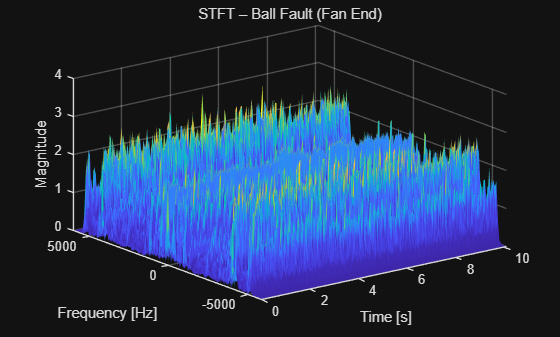

xlabel("Time [s]"); ylabel("Acceleration [m/s^2]");
legend("Raw","Envelope"); grid on;
figure;
subplot(2,1,1);
plot(OuterFeat_DE.EnvelopeSpectrum.Time, outer_DE, 'b'); hold on;
plot(OuterFeat_DE.EnvelopeSpectrum.Time, OuterFeat_DE.EnvelopeSpectrum.Signal, 'r', 'LineWidth', 1.2);
title("Envelope (Time Domain) – Outer Fault (Drive End)");
xlabel("Time [s]"); ylabel("Acceleration [m/s^2]");
legend("Raw","Envelope"); grid on;

subplot(2,1,2);

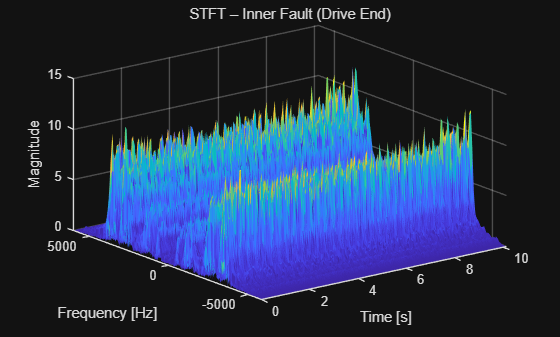

plot(OuterFeat_FE.EnvelopeSpectrum.Time, outer_FE, 'b'); hold on;
plot(OuterFeat_FE.EnvelopeSpectrum.Time, OuterFeat_FE.EnvelopeSpectrum.Signal, 'r', 'LineWidth', 1.2);
title("Envelope (Time Domain) – Outer Fault (Fan End)");
xlabel("Time [s]"); ylabel("Acceleration [m/s^2]");
legend("Raw","Envelope"); grid on;
figure;
subplot(2,1,1);
plot(NormalFeat_DE.EnvelopeSpectrum.Time, normal_DE, 'b'); hold on;
plot(NormalFeat_DE.EnvelopeSpectrum.Time, NormalFeat_DE.EnvelopeSpectrum.Signal, 'r', 'LineWidth', 1.2);
title("Envelope (Time Domain) – Normal (Drive End)");
xlabel("Time [s]"); ylabel("Acceleration [m/s^2]");

legend("Raw","Envelope"); grid on;

subplot(2,1,2);
plot(NormalFeat_FE.EnvelopeSpectrum.Time, normal_FE, 'b'); hold on;
plot(NormalFeat_FE.EnvelopeSpectrum.Time, NormalFeat_FE.EnvelopeSpectrum.Signal, 'r', 'LineWidth', 1.2);
title("Envelope (Time Domain) – Normal (Fan End)");
xlabel("Time [s]"); ylabel("Acceleration [m/s^2]");
legend("Raw","Envelope"); grid on;

### 4. STFT

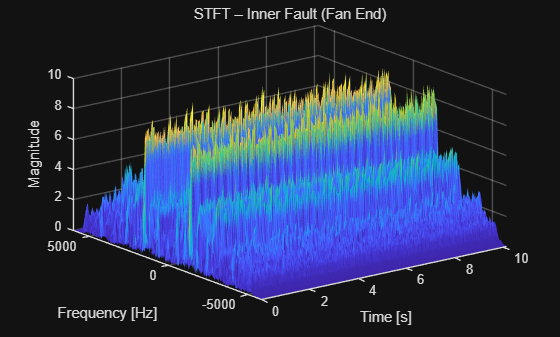

% STFT – Ball Fault (Drive End)
figure;
S = BallFeat_DE.STFT.S;
F = BallFeat_DE.STFT.F;

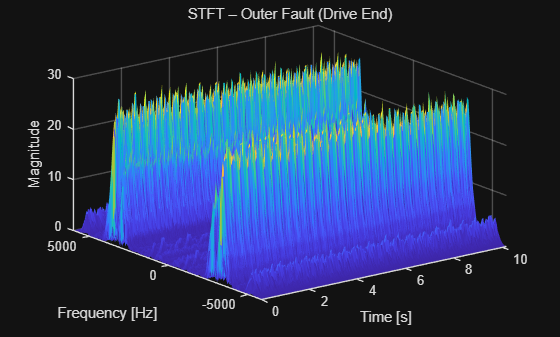

T = BallFeat_DE.STFT.T;

surf(T, F, abs(S), "EdgeColor","none");
xlabel("Time [s]");
ylabel("Frequency [Hz]");
zlabel("Magnitude");
title("STFT – Ball Fault (Drive End)");
% STFT – Ball Fault (Fan End)
figure;
S = BallFeat_FE.STFT.S;
F = BallFeat_FE.STFT.F;
T = BallFeat_FE.STFT.T;


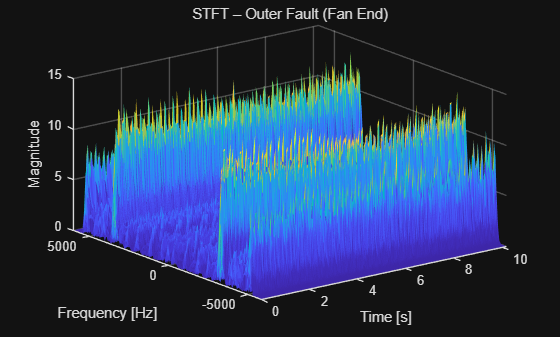

surf(T, F, abs(S), "EdgeColor","none");
xlabel("Time [s]");
ylabel("Frequency [Hz]");
zlabel("Magnitude");
title("STFT – Ball Fault (Fan End)");
% STFT – Inner Fault (Drive End)
figure;
S = abs(InnerFeat_DE.STFT.S);
F = InnerFeat_DE.STFT.F;
T = InnerFeat_DE.STFT.T;

surf(T, F, abs(S), 'EdgeColor', 'none');
xlabel('Time [s]');

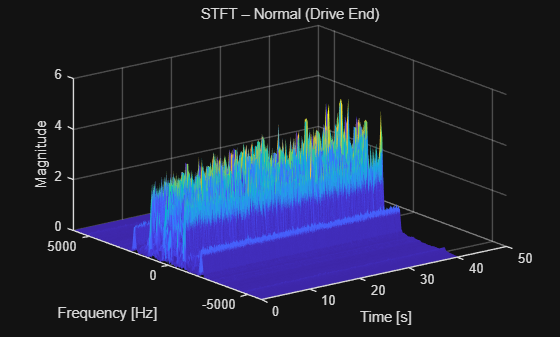

ylabel('Frequency [Hz]');
zlabel('Magnitude');
title('STFT – Inner Fault (Drive End)');

% STFT – Inner Fault (Fan End)
figure;
S = abs(InnerFeat_FE.STFT.S);
F = InnerFeat_FE.STFT.F;
T = InnerFeat_FE.STFT.T;

surf(T, F, abs(S), 'EdgeColor', 'none');
xlabel('Time [s]');
ylabel('Frequency [Hz]');

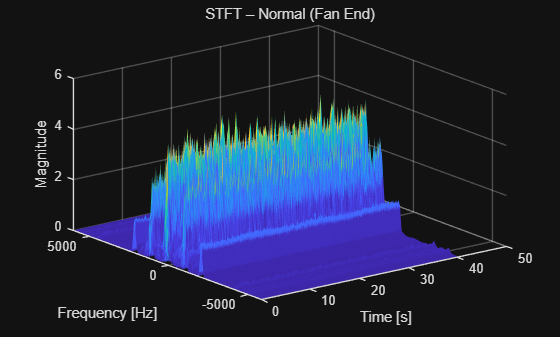

zlabel('Magnitude');
title('STFT – Inner Fault (Fan End)');


% STFT – Outer Fault (Drive End)
figure;
S = abs(OuterFeat_DE.STFT.S);
F = OuterFeat_DE.STFT.F;
T = OuterFeat_DE.STFT.T;

surf(T, F, S, 'EdgeColor', 'none');
xlabel('Time [s]');
ylabel('Frequency [Hz]');

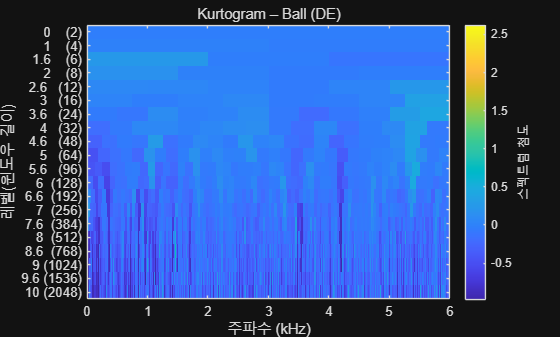

zlabel('Magnitude');
title('STFT – Outer Fault (Drive End)');


% STFT – Outer Fault (Fan End)
figure;

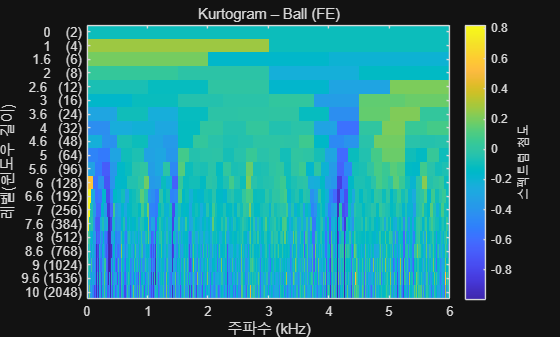

S = abs(OuterFeat_FE.STFT.S);
F = OuterFeat_FE.STFT.F;
T = OuterFeat_FE.STFT.T;

surf(T, F, abs(S), 'EdgeColor', 'none');

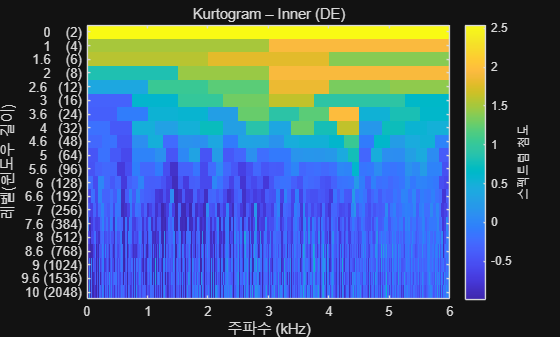

xlabel('Time [s]');
ylabel('Frequency [Hz]');
zlabel('Magnitude');
title('STFT – Outer Fault (Fan End)');


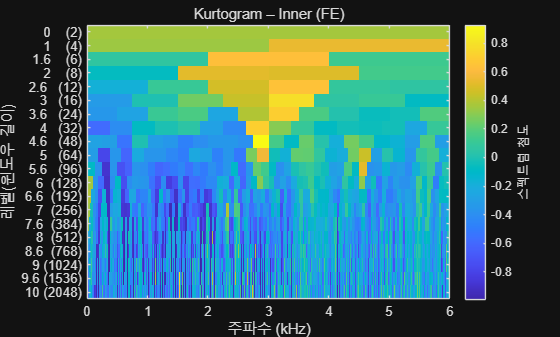


% STFT – Normal (Drive End)
figure;
S = abs(NormalFeat_DE.STFT.S);
F = NormalFeat_DE.STFT.F;

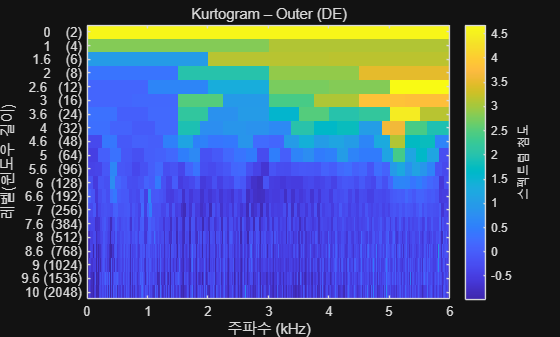

T = NormalFeat_DE.STFT.T;

surf(T, F, abs(S), 'EdgeColor', 'none');
xlabel('Time [s]');
ylabel('Frequency [Hz]');

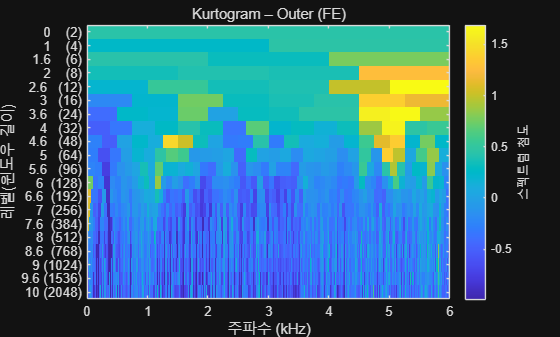

zlabel('Magnitude');
title('STFT – Normal (Drive End)');


% STFT – Normal (Fan End)

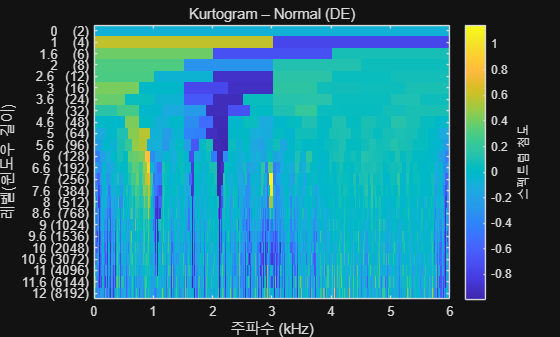

figure;
S = abs(NormalFeat_FE.STFT.S);
F = NormalFeat_FE.STFT.F;
T = NormalFeat_FE.STFT.T;


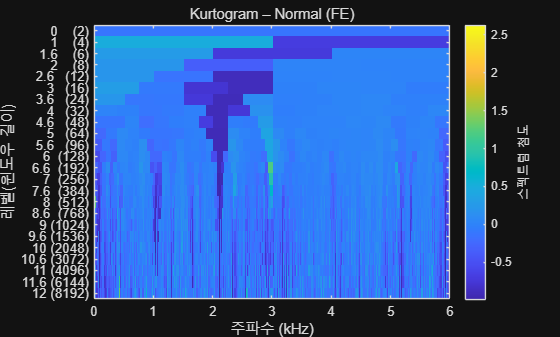

surf(T, F, abs(S), 'EdgeColor', 'none');
xlabel('Time [s]');
ylabel('Frequency [Hz]');
zlabel('Magnitude');
title('STFT – Normal (Fan End)');

### 5. Kurtogram

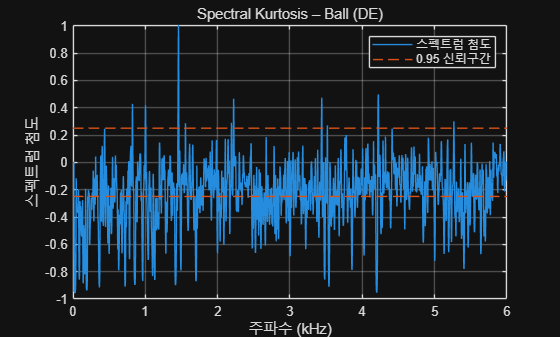

% Kurtogram – Ball (DE)
figure;
kurtogram(ball_DE, fs);
title("Kurtogram – Ball (DE)");

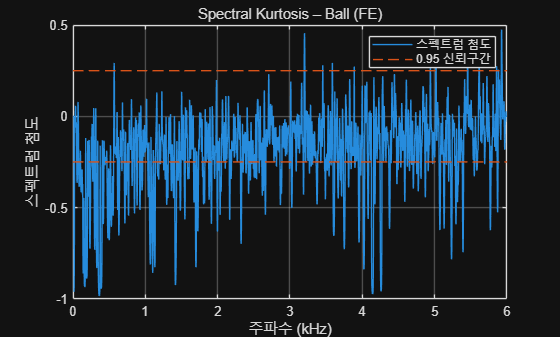


% Kurtogram – Ball (FE)
figure;
kurtogram(ball_FE, fs);

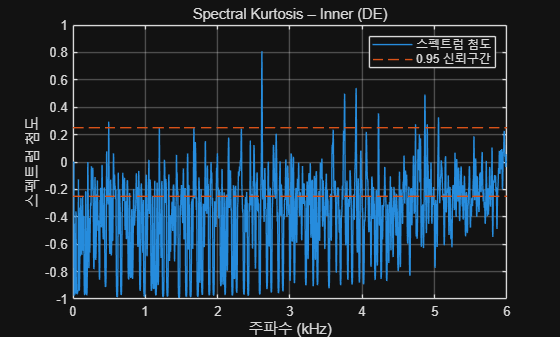

title("Kurtogram – Ball (FE)");

% Kurtogram – Inner (DE)
figure;

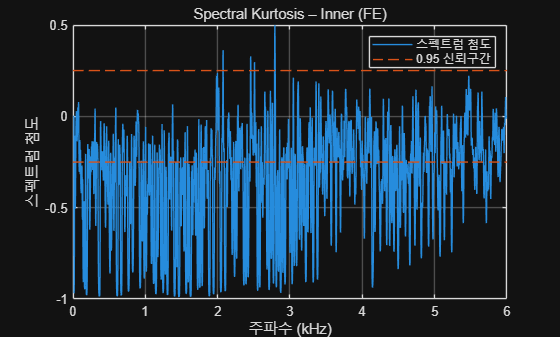

kurtogram(inner_DE, fs);
title("Kurtogram – Inner (DE)");

% Kurtogram – Inner (FE)

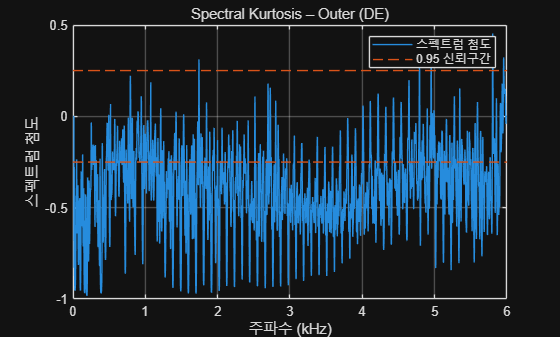

figure;
kurtogram(inner_FE, fs);
title("Kurtogram – Inner (FE)");


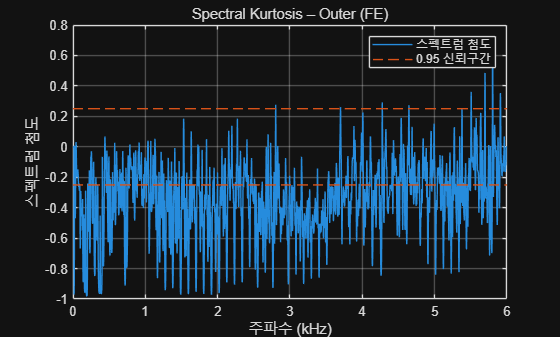

% Kurtogram – Outer (DE)
figure;
kurtogram(outer_DE, fs);
title("Kurtogram – Outer (DE)");

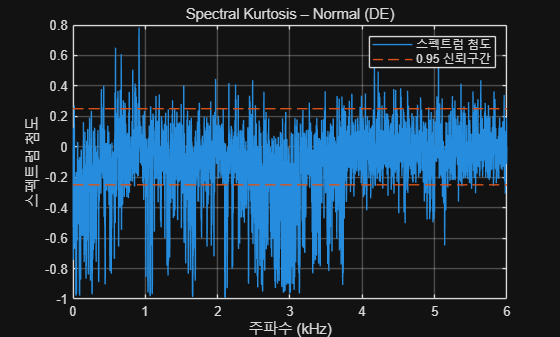


% Kurtogram – Outer (FE)
figure;
kurtogram(outer_FE, fs);

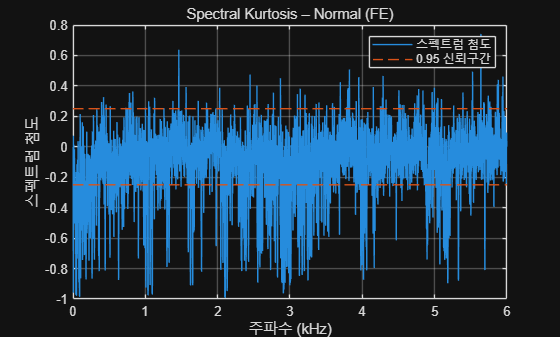

title("Kurtogram – Outer (FE)");

% Kurtogram – Normal (DE)
figure;

kurtogram(normal_DE, fs);
title("Kurtogram – Normal (DE)");

% Kurtogram – Normal (FE)
figure;
kurtogram(normal_FE, fs);
title("Kurtogram – Normal (FE)");

     Class        mean         std         rms         sra         aav       energy     peak       ppv        if        sf        cf        mf         sk          kt  
    ________    _________    ________    ________    ________    ________    ______    _______    ______    ______    ______    ______    ______    _________    ______

    "Ball"      0.0038918     0.13901     0.13907    0.094363     0.11122    2348.1    0.65965    1.2993    5.9312    1.2504    4.7433    6.9905    0.0074533    2.9638
    "Inner"      0.005801     0.29284     0.29289     0.16484     0.20764     10465     1.5808    2.9838    7.6131    1.4105    5.3973    9.5902      0.13043    5.5423
    "Outer"     0.0040611     0.59194     0.59195     0.26626     0.36646     42898     3.1123    6.1242    8.4927    1.6153    5.2577    11.689     0.033401     7.595
    "Normal"     0.012564    0.065152    0.066352    0.045547    0.053471    2130.4    0.34588    0.6634    6.4686    1.2409    5.2129     7.594     -0.17305  

### 6. Spectral Kurtosis

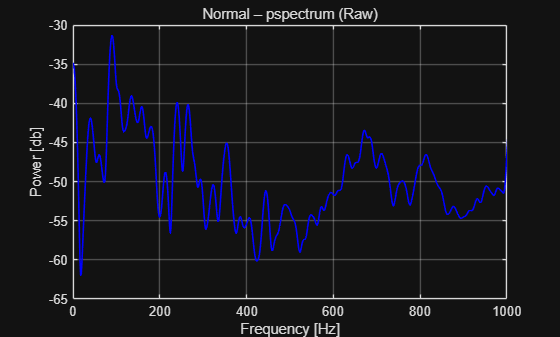

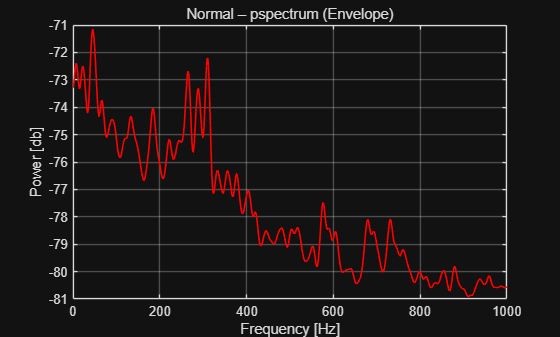

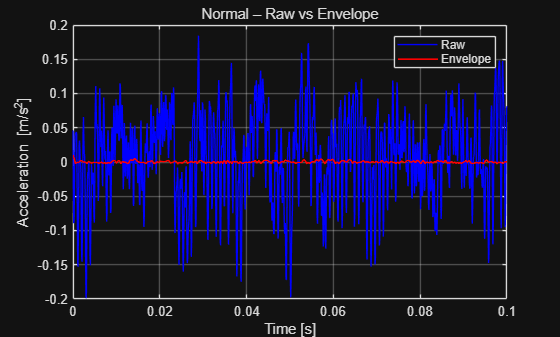

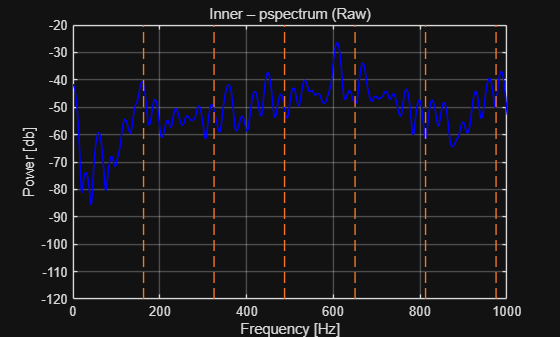

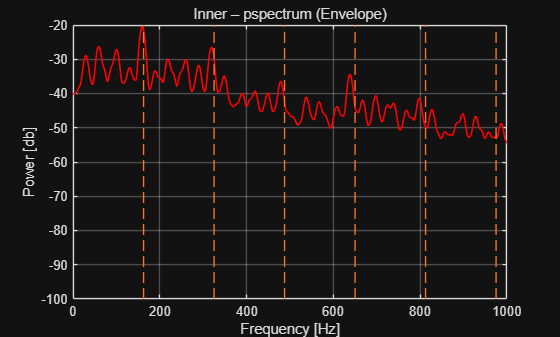

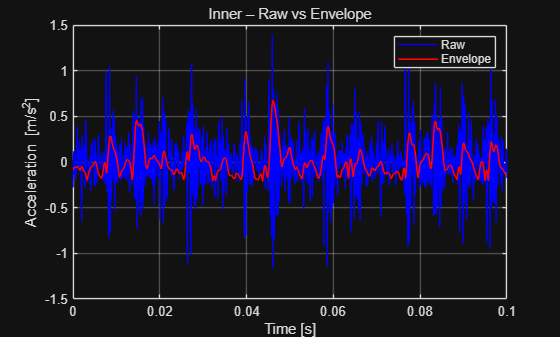

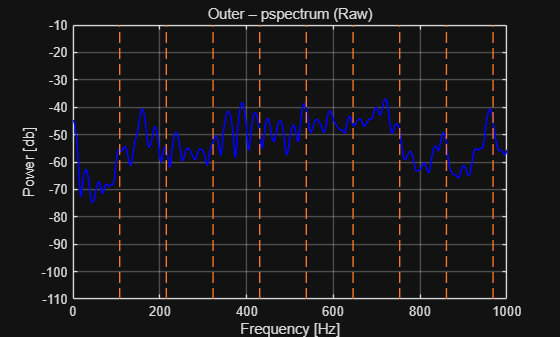

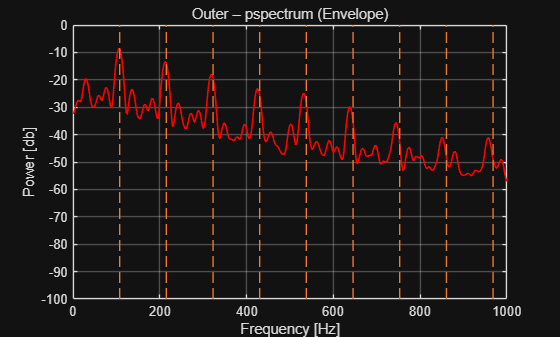

% Spectral Kurtosis – Ball (DE)
figure;
pkurtosis(ball_DE, fs);
title("Spectral Kurtosis – Ball (DE)");
% Spectral Kurtosis – Ball (FE)
figure;
pkurtosis(ball_FE, fs);
title("Spectral Kurtosis – Ball (FE)");
% Spectral Kurtosis – Inner (DE)
figure;
pkurtosis(inner_DE, fs);
title("Spectral Kurtosis – Inner (DE)");
% Spectral Kurtosis – Inner (FE)
figure;
pkurtosis(inner_FE, fs);
title("Spectral Kurtosis – Inner (FE)");
% Spectral Kurtosis – Outer (DE)
figure;
pkurtosis(outer_DE, fs);
title("Spectral Kurtosis – Outer (DE)");
% Spectral Kurtosis – Outer (FE)
figure;
pkurtosis(outer_FE, fs);
title("Spectral Kurtosis – Outer (FE)");
% Spectral Kurtosis – Normal (DE)
figure;
pkurtosis(normal_DE, fs);
title("Spectral Kurtosis – Normal (DE)");
% Spectral Kurtosis – Normal (FE)
figure;
pkurtosis(normal_FE, fs);
title("Spectral Kurtosis – Normal (FE)");

## Frequency Analysis and Camparison

**1. In Time Domain**

**The value of rms and peak of normal state(0.066, 0.345) is lower than ball(0.139, 0.659), inner(0.292, 1.580), outer(0.591, 3.112) fault.**

**As ppv value shows, there is bigger amplitude of vibration when there is a defect. (outer(6.124) > inner(2.983) > ball(1.299) > normal(0.663))**

disp(All_time_features_DE);

**2. In Frequency Domain**

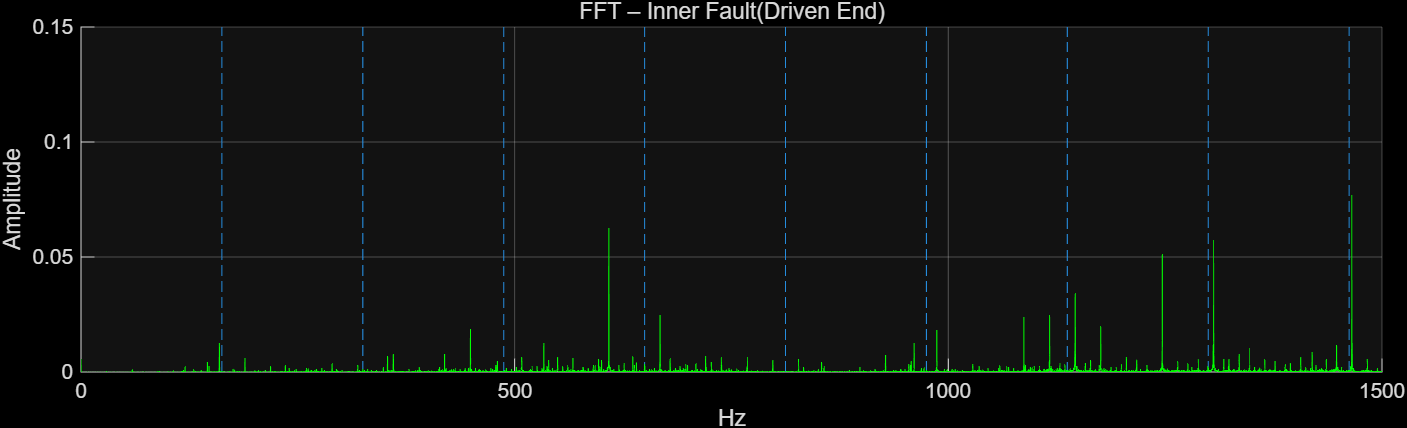

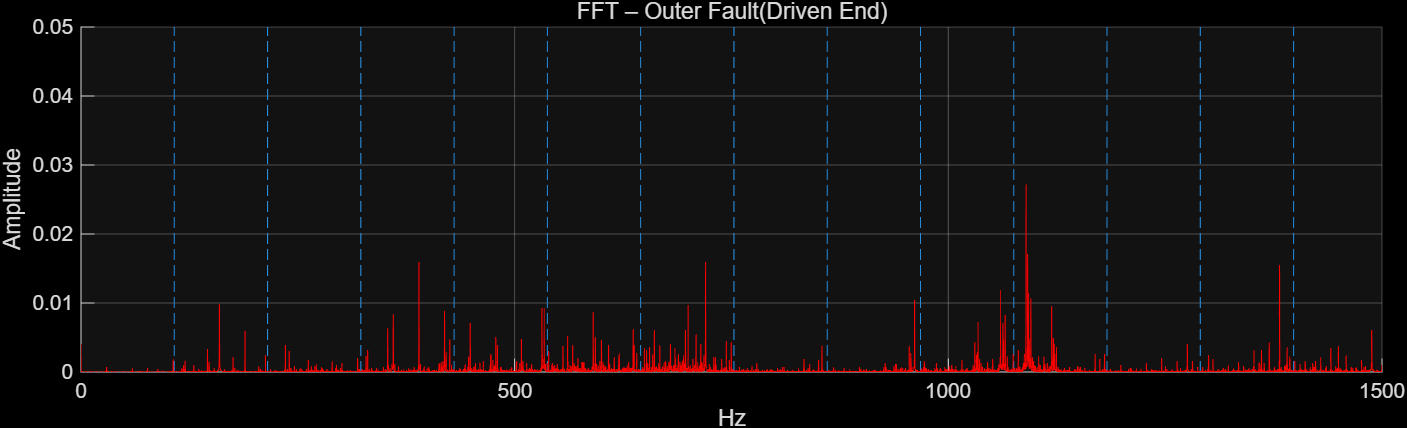

For FFT of ineer fault, few frequencies are matched with BPFI, but still there is lots of noise.

For FFT of outer fault, the frequencies are not clearly matched with BPFO.

To have a clear analysis, power spectrum graphs are included below

signals = {normal_DE, inner_DE, outer_DE};
envs    = {NormalFeat_DE.EnvelopeSpectrum.Signal, InnerFeat_DE.EnvelopeSpectrum.Signal, OuterFeat_DE.EnvelopeSpectrum.Signal};

names   = ["Normal", "Inner", "Outer"];
bp_freq = {[], BPFI, BPFO};

for k = 1:3

    raw = signals{k};
    env = envs{k};
    name = names(k);
    defect = bp_freq{k};

KurtosisTable_Before = 3×3 table
    Classes     RawKurtosis    EnvelopeKurtosis
    ________    ___________    ________________

    "Inner"       5.5423            5.0909     
    "Outer"        7.595            4.3189     
    "Normal"      2.9306             3.909     


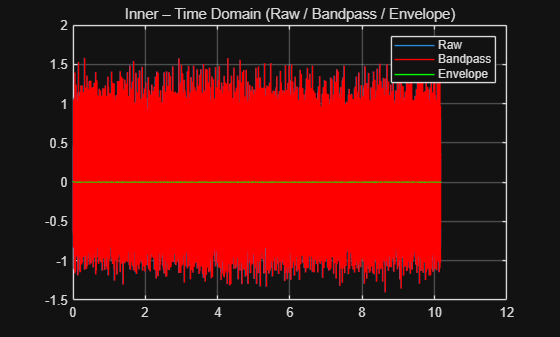


    figure;
    [Praw, fraw] = pspectrum(raw, fs);
    plot(fraw, 10*log10(Praw), 'b', 'LineWidth', 1.2); hold on; grid on;
    if ~isempty(defect)
        helperPlotCombs(50, defect);
    end
    xlabel('Frequency [Hz]');
    ylabel('Power [db]');
    title(name + " – pspectrum (Raw)");
    xlim([0 1000]);


    figure;
    [Penv, fenv] = pspectrum(env, fs);
    plot(fenv, 10*log10(Penv), 'r', 'LineWidth', 1.2); hold on; grid on;
    if ~isempty(defect)
        helperPlotCombs(10, defect);
    end
    xlabel('Frequency [Hz]');
    ylabel('Power [db]');
    title(name + " – pspectrum (Envelope)");
    xlim([0 1000]);


    t_raw = (0:length(raw)-1)/fs;
    t_env = eval(name + "Feat_DE.EnvelopeSpectrum.Time");


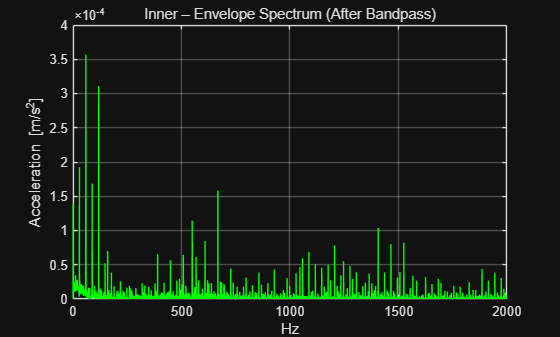

    idx_r = (t_raw >= 0 & t_raw <= 0.1);
    idx_e = (t_env >= 0 & t_env <= 0.1);

    figure;
    plot(t_raw(idx_r), raw(idx_r), 'b'); hold on; grid on;
    plot(t_env(idx_e), env(idx_e), 'r', 'LineWidth', 1.2);

    title(name + " – Raw vs Envelope");
    xlabel("Time [s]");
    ylabel("Acceleration [m/s^2]");
    legend("Raw","Envelope");

end

Power spectrums before envelope clearly show that they are unmatched with BPFI and BPFO. Because of envelope, the true fault-related modulation which is hidden in the high-frequency resonance band. It is demodulated into a low-frequency signal whose spectrum aligns directly with the theoretical fault frequencies.Therefore, amplitude modulation pattern is more clear. 

% Raw and envelope kurtosis
kurt_inner_raw  = kurtosis(inner_DE);
kurt_outer_raw  = kurtosis(outer_DE);
kurt_normal_raw = kurtosis(normal_DE);

kurt_inner_env  = kurtosis(InnerFeat_DE.EnvelopeSpectrum.Signal);
kurt_outer_env  = kurtosis(OuterFeat_DE.EnvelopeSpectrum.Signal);
kurt_normal_env = kurtosis(NormalFeat_DE.EnvelopeSpectrum.Signal);

Classes = ["Inner"; "Outer"; "Normal"];
RawKurtosis = [kurt_inner_raw; kurt_outer_raw; kurt_normal_raw];
EnvelopeKurtosis = [kurt_inner_env; kurt_outer_env; kurt_normal_env];

KurtosisTable_Before = table(Classes, RawKurtosis, EnvelopeKurtosis)

Even though the modulation is matched after envelope, the kurtosis of inner and outer have been decreased. There is not enough gap between normal and defected state. The solution is bandpass filter.

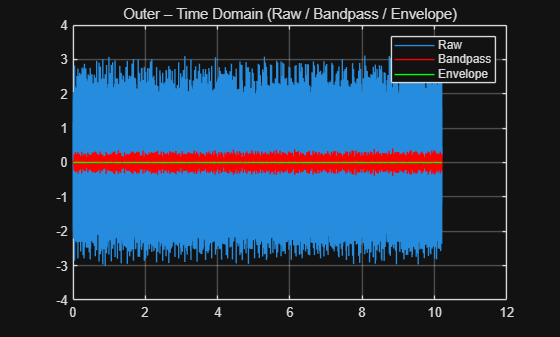

% Inner bandpass
[~,~,~, fc_inner, ~, bw_inner] = kurtogram(inner_DE, fs);

f1_inner = max(fc_inner - bw_inner/2, 0.1);
f2_inner = min(fc_inner + bw_inner/2, fs/2 - 1);

bpf_inner = designfilt('bandpassfir','FilterOrder',200, ...
    'CutoffFrequency1', f1_inner, 'CutoffFrequency2', f2_inner, ...

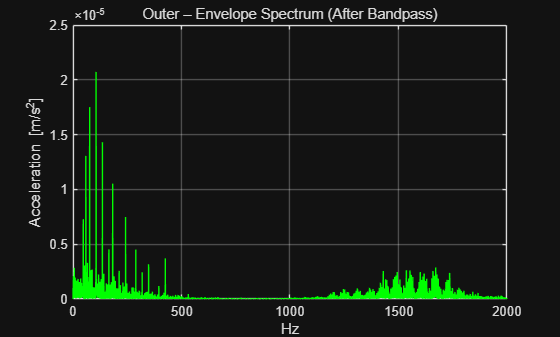

    'SampleRate', fs);

inner_band = filter(bpf_inner, inner_DE);

[pEnv_inner_band, fEnv_inner_band, xEnv_inner_band, tEnv_inner_band] = ...
    envspectrum(inner_band, fs, 'FilterOrder',200, ...

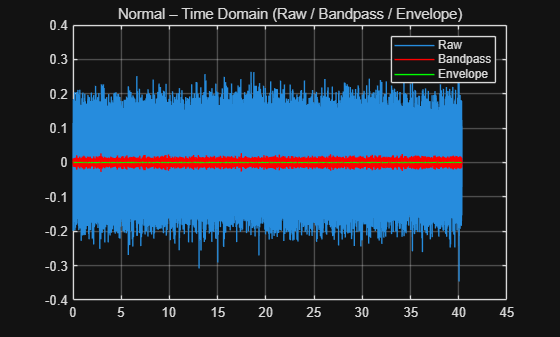

    'Band',[f1_inner/fs, f2_inner/fs]);

kurt_inner_band     = kurtosis(inner_band);
kurt_inner_env_band = kurtosis(xEnv_inner_band);

figure;
t = (0:length(inner_DE)-1)/fs;
plot(t, inner_DE); hold on; grid on;
plot(t, inner_band,'r');
plot(tEnv_inner_band, xEnv_inner_band,'g');
title("Inner – Time Domain (Raw / Bandpass / Envelope)");
legend("Raw","Bandpass","Envelope");

figure;
plot(fEnv_inner_band, pEnv_inner_band,'g'); hold on; grid on;
title("Inner – Envelope Spectrum (After Bandpass)");
xlim([0 2000]);
xlabel("Hz"); ylabel("Acceleration [m/s^2]");


% Outer bandpass
[~,~,~, fc_outer, ~, bw_outer] = kurtogram(outer_DE, fs);

f1_outer = max(fc_outer - bw_outer/2, 0.1);

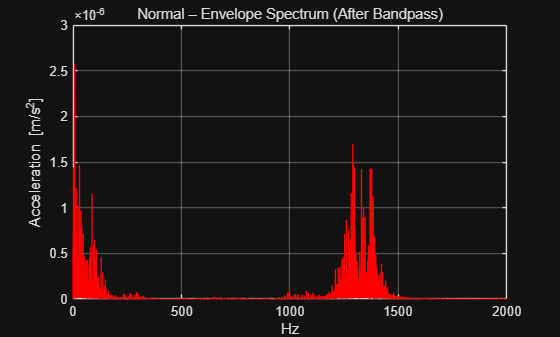

f2_outer = min(fc_outer + bw_outer/2, fs/2 - 1);

bpf_outer = designfilt('bandpassfir','FilterOrder',200, ...
    'CutoffFrequency1', f1_outer, 'CutoffFrequency2', f2_outer, ...
    'SampleRate', fs);


outer_band = filter(bpf_outer, outer_DE);

[pEnv_outer_band, fEnv_outer_band, xEnv_outer_band, tEnv_outer_band] = ...
    envspectrum(outer_band, fs, 'FilterOrder',200, ...
    'Band',[f1_outer/fs, f2_outer/fs]);

kurt_outer_band     = kurtosis(outer_band);

KurtosisTable = 3×4 table
     Class      RawKurtosis    EnvBeforeKurtosis    EnvAfterKurtosis
    ________    ___________    _________________    ________________

    "Inner"       5.5423            5.0909               10.082     
    "Outer"        7.595            4.3189               7.3003     
    "Normal"      2.9306             3.909               3.8674     


kurt_outer_env_band = kurtosis(xEnv_outer_band);

figure;
t = (0:length(outer_DE)-1)/fs;
plot(t, outer_DE); hold on; grid on;
plot(t, outer_band,'r');
plot(tEnv_outer_band, xEnv_outer_band,'g');
title("Outer – Time Domain (Raw / Bandpass / Envelope)");
legend("Raw","Bandpass","Envelope");

figure;
plot(fEnv_outer_band, pEnv_outer_band,'g'); grid on;
xlim([0 2000]);
title("Outer – Envelope Spectrum (After Bandpass)");
xlabel("Hz"); ylabel("Acceleration [m/s^2]");


% Normal bandpass
[~,~,~, fc_normal, ~, bw_normal] = kurtogram(normal_DE, fs);

f1_normal = max(fc_normal - bw_normal/2, 0.1);
f2_normal = min(fc_normal + bw_normal/2, fs/2 - 1);

bpf_normal = designfilt('bandpassfir','FilterOrder',200, 'CutoffFrequency1', f1_normal, 'CutoffFrequency2', f2_normal, 'SampleRate', fs);

normal_band = filter(bpf_normal, normal_DE);

[pEnv_normal_band, fEnv_normal_band, xEnv_normal_band, tEnv_normal_band] =  envspectrum(normal_band, fs, 'FilterOrder',200, 'Band',[f1_normal/fs, f2_normal/fs]);

kurt_normal_band     = kurtosis(normal_band);
kurt_normal_env_band = kurtosis(xEnv_normal_band);

figure;
t = (0:length(normal_DE)-1)/fs;
plot(t, normal_DE); hold on; grid on;
plot(t, normal_band,'r');
plot(tEnv_normal_band, xEnv_normal_band,'g');
title("Normal – Time Domain (Raw / Bandpass / Envelope)");
legend("Raw","Bandpass","Envelope");

figure;
plot(fEnv_normal_band, pEnv_normal_band,'r'); grid on;
title("Normal – Envelope Spectrum (After Bandpass)");
xlim([0, 2000]);
xlabel("Hz"); ylabel("Acceleration [m/s^2]");
% Final kurtosis table
Class = ["Inner"; "Outer"; "Normal"];
RawKurtosis       = [kurt_inner_raw; kurt_outer_raw; kurt_normal_raw];
EnvBeforeKurtosis = [kurt_inner_env; kurt_outer_env; kurt_normal_env];
EnvAfterKurtosis  = [kurt_inner_env_band; kurt_outer_env_band; kurt_normal_env_band];

KurtosisTable = table(Class, RawKurtosis, EnvBeforeKurtosis, EnvAfterKurtosis)

After bandpass filter, the kurtosis between normal and defected states have a bigger gap. 

## Conclusion

This project is proceed to extract feature. These feature data will be used to do machine laerning. Therefore, clear differencies between each class is required for a better model. To get a nice feature extraction, the raw data is analysed in time and frequency domain. Especially, it is analyzed in frequency domain because it is vibration data. Data from defected states have an impact and harmonical frequencies which are matched with BPFI or BPFO. However, raw data is not clearly showing that, so envelope method is applied. That method successfully extracts only harmonical frequencies which are matched with BPFI or BPFO, but kurtosis has been decrease. Bandpass filter is utilized to solve it. 